filePath = "C:\Users\User\Desktop\uni\ATD\Projeto1\55\"

filePath = "C:\Users\User\Desktop\uni\ATD\Projeto1\55\"

audioFiles = {"0_55_0.wav", "1_55_0.wav", "2_55_0.wav", "3_55_0.wav", "4_55_0.wav", "5_55_0.wav", "6_55_0.wav", "7_55_0.wav", "8_55_0.wav", "9_55_0.wav"}

audioFiles = 1×10 cell array
    {["0_55_0.wav"]}    {["1_55_0.wav"]}    {["2_55_0.wav"]}    {["3_55_0.wav"]}    {["4_55_0.wav"]}    {["5_55_0.wav"]}    {["6_55_0.wav"]}    {["7_55_0.wav"]}    {["8_55_0.wav"]}    {["9_55_0.wav"]}


y = cell(1, numel(audioFiles))

y = 1×10 cell array
    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}    {0×0 double}


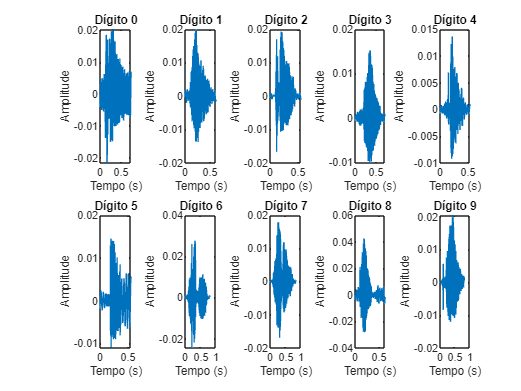


for i = 1:numel(audioFiles)
    file = append(filePath,audioFiles{i});
    [y{i}, Fs] = audioread(file);
end

grafico(y,Fs)


%silencio

limite = 5e-3

limite = 0.0050

for j = 1: length(y)
    duracaoJanela =  0.002;
    comprimentoJanela = duracaoJanela * Fs;
    comrimentoTotal = length(y{j});
    numeroJanelas = floor(comrimentoTotal/comprimentoJanela);
    yNovo = [];
    for i = 1 : numeroJanelas
        yJanela = y{j}((i-1)*comprimentoJanela+1:comprimentoJanela*i);
        if max(yJanela) > limite
            yNovo = y{j}((i-1)*comprimentoJanela+1:end)
            break;
        end
    end
    y{j} = yNovo
end

yNovo =     0.0045
    0.0047
    0.0048
    0.0045
    0.0042
    0.0039
    0.0039
    0.0040
    0.0043
    0.0045


y = 1×10 cell array
    {30288×1 double}    {29273×1 double}    {26566×1 double}    {33892×1 double}    {25565×1 double}    {26166×1 double}    {38475×1 double}    {39910×1 double}    {29663×1 double}    {38838×1 double}


yNovo =    -0.0024
   -0.0025
   -0.0025
   -0.0026
   -0.0026
   -0.0027
   -0.0027
   -0.0027
   -0.0028
   -0.0028


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {26566×1 double}    {33892×1 double}    {25565×1 double}    {26166×1 double}    {38475×1 double}    {39910×1 double}    {29663×1 double}    {38838×1 double}


yNovo =    -0.0024
    0.0001
    0.0022
    0.0024
    0.0012
    0.0008
    0.0008
    0.0009
    0.0004
    0.0000


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {33892×1 double}    {25565×1 double}    {26166×1 double}    {38475×1 double}    {39910×1 double}    {29663×1 double}    {38838×1 double}


yNovo =    -0.0025
   -0.0025
   -0.0025
   -0.0026
   -0.0026
   -0.0025
   -0.0024
   -0.0023
   -0.0022
   -0.0020


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {23620×1 double}    {25565×1 double}    {26166×1 double}    {38475×1 double}    {39910×1 double}    {29663×1 double}    {38838×1 double}


yNovo =     0.0002
    0.0013
    0.0009
    0.0018
    0.0053
    0.0069
    0.0052
    0.0019
    0.0004
    0.0006


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {23620×1 double}    {18365×1 double}    {26166×1 double}    {38475×1 double}    {39910×1 double}    {29663×1 double}    {38838×1 double}


yNovo =    -0.0038
   -0.0039
   -0.0041
   -0.0040
   -0.0042
   -0.0043
   -0.0044
   -0.0047
   -0.0047
   -0.0048


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {23620×1 double}    {18365×1 double}    {17334×1 double}    {38475×1 double}    {39910×1 double}    {29663×1 double}    {38838×1 double}


yNovo =     0.0036
    0.0017
   -0.0013
   -0.0036
   -0.0040
   -0.0022
    0.0004
    0.0027
    0.0034
    0.0021


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {23620×1 double}    {18365×1 double}    {17334×1 double}    {32427×1 double}    {39910×1 double}    {29663×1 double}    {38838×1 double}


yNovo =     0.0010
    0.0018
    0.0013
   -0.0005
   -0.0011
   -0.0009
    0.0001
    0.0010
    0.0007
    0.0008


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {23620×1 double}    {18365×1 double}    {17334×1 double}    {32427×1 double}    {32326×1 double}    {29663×1 double}    {38838×1 double}


yNovo =     0.0042
    0.0042
    0.0042
    0.0042
    0.0043
    0.0043
    0.0043
    0.0044
    0.0044
    0.0042


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {23620×1 double}    {18365×1 double}    {17334×1 double}    {32427×1 double}    {32326×1 double}    {26591×1 double}    {38838×1 double}


yNovo =    -0.0023
   -0.0023
    0.0006
    0.0004
   -0.0008
   -0.0017
   -0.0015
    0.0001
    0.0001
   -0.0006


y = 1×10 cell array
    {30288×1 double}    {23513×1 double}    {21574×1 double}    {23620×1 double}    {18365×1 double}    {17334×1 double}    {32427×1 double}    {32326×1 double}    {26591×1 double}    {33750×1 double}


tempoMax = 0

tempoMax = 0

for j = 1:length(y) 
    duracaoJanela =  0.002;
    comprimentoJanela = duracaoJanela * Fs;
    comrimentoTotal = length(y{j});
    numeroJanelas = floor(comrimentoTotal/comprimentoJanela);
    yNovo = [];
    for i = 1: numeroJanelas
        yJanela = y{j}((i-1)*comprimentoJanela+1:comprimentoJanela*i);
        if max(yJanela) < limite
            if (i-1)*comprimentoJanela > tempoMax
                tempoMax = (i-1)*comprimentoJanela
                break;
            end
        end
    end
end

tempoMax = 576

tempoMax = 672

tempoMax = 1536

tempoMax = 1728

tempoMax = 2016

tempoMax = 2304

tempoMax = 5664

tempoMax = 6816

tempoMax = 7008

tempoMax = 7296

% disp(tempoMax)
% figure
% grafico (y, Fs)
% yn = [];
% for i = 1:length(y)
%     yn = y{i}(1:tempoMax);
%     y{i} = yn;
% end
% figure
% grafico (y, Fs)

%adicionar silencios no fim
duracaomax = length(y{1})/Fs

duracaomax = 0.6310

for k = 2:length(y)
    duracao = length(y{k})/Fs;
    if duracao > duracaomax
        duracaomax = duracao
    end    
end

duracaomax = 0.6756

duracaomax = 0.7031


for f = 1:length(y)
    duracao = length(y{f})/Fs;
    if duracao < duracaomax
        adicionar = duracaomax-duracao;
        silencio = zeros(round(adicionar * Fs), 1);
        y{i} = [y{i}, silencio];
    end
end

Index exceeds the number of array elements. Index must not exceed 10.

grafico(y,Fs);

%adicionar silencio no fim v2
% 
% duracaomax = 0.6
% for i = 1:length(y)
%     if(length(y{i}) < duracaomax * Fs)
%         y{i} = [y{i}; zeros(duracaomax*Fs - length(y{i}), 1)];
%     else
%         y{i} = y{i}(1:duracaomax*Fs);
%     end
% end
% grafico(y, Fs)

% normalizar amplitude
amplitudemax = max(abs(y{1}));
amplitudemin = min(abs(y{1}));
for l = 2:length(y)
    amplitudeM = max(abs(y{l}));
    amplitudem = min(abs(y{l}));
    if amplitudeM > amplitudemax
        amplitudemax = amplitudeM;
    end
    if amplitudem < amplitudemin
        amplitudemin = amplitudem;
    end
end

valorMax = amplitudemax/ length(y);
valorMin = amplitudemin/ length(y);
for w = 1:length(y)
    y{w} = y{w}/valorMax;
    y{w} = y{w}/valorMin;
end
grafico(y, Fs)

## Funções

function grafico(y, Fs)
for i = 1:numel(y)
    subplot(2,5,i)
    t = (0:length(y{i})-1) / Fs;
    plot(t, y{i});
    xlabel('Tempo (s)');
    ylabel('Amplitude');
    title(['Dígito ', num2str(i-1)]);
end
end